Mediante Función Voronoi

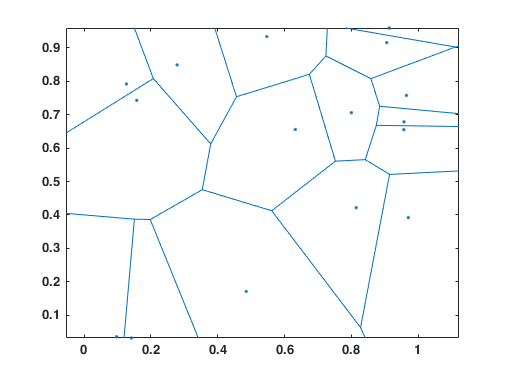

rng default;
x = rand([1 16]);
y = rand([1 16]);
voronoi(x,y)
axis equal

Mediante Ciclos

Plano=zeros(256);
sx = randi([1,256],16,1);
sy = randi([1,256],16,1);
color = (1:16:256)';
Pts=[sx,sy,color]

Pts =     71   182     1
    12   194    17
    25    71    33
   211   175    49
   178   168    65
    82    42    81
   244    31    97
     9   128   113
   113   246   129
    98    88   145


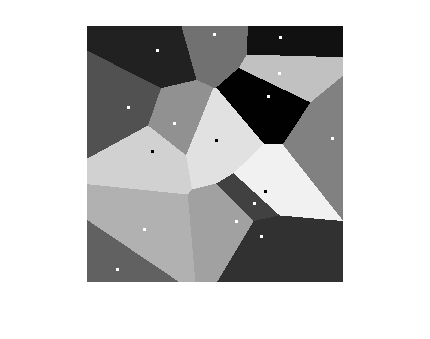

[imax,jmax]=size(Plano);
for i=1:imax
    for j= 1:jmax
        dmin=256;
        for k=Pts'
            d=sqrt(((i-k(1))^2)+((j-k(2))^2));
            if d<2
                dmin=d;
                if k(3)>200
                    Plano(i,j)=0;
                else
                    Plano(i,j)=256;
                end
                
            elseif d<dmin
                dmin=d;
                Plano(i,j)=k(3);
            end
        end
    end
end
imshow(uint8(Plano))

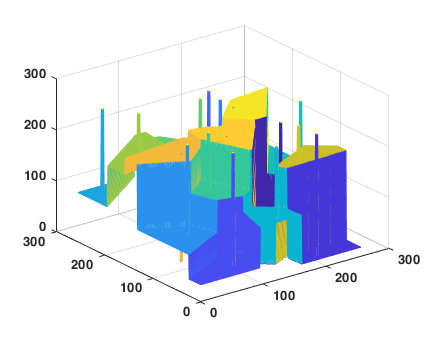

mesh(Plano)